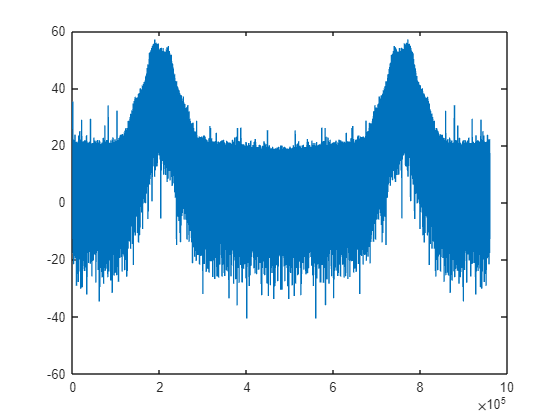

clear; 
close all; 
syms x t cs xc xl f1 xs xls xlsj xn xz xzs y yn ys xd csh xdl xdld data data2
load("Radio_signal.mat")

x = raw_radio_94_2MHz;
Fs = 960000;
Fc = 200000;
Fcd = 57000;
t = 0:(1/Fs):10;
plot(20*log10(abs(fft(x, Fs))))

x = x(1:length(t));
cs = cos(2*pi*Fc*t);
xc = x'.*cs;
f1 = fir1(101, 0.1);

xl = filter(f1, 1, xc);

si = -sin(2*pi*Fc*t);
xs = x'.*si;
xls = filter(f1, 1, xs);
xlsj = xls * 1j;

xn = xlsj + xl;

xz = circshift(xn, -1);
xzs = conj(xz);
y = xn.*xzs;
yn = angle(y);

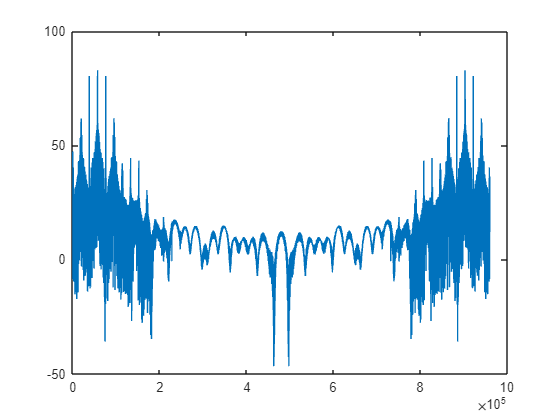

ys = downsample(yn, 5);
sound(ys, 192000)
csh = cos(2*pi*Fcd*t);
xd = yn .* csh;
plot(20*log10(abs(fft(xd, Fs))))

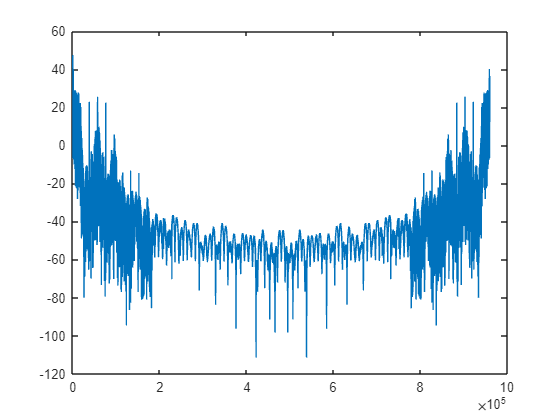

f2 = fir1(101, 0.004583);
xdl = filter(f2, 1, xd);
plot(20*log10(abs(fft(xdl, Fs))))

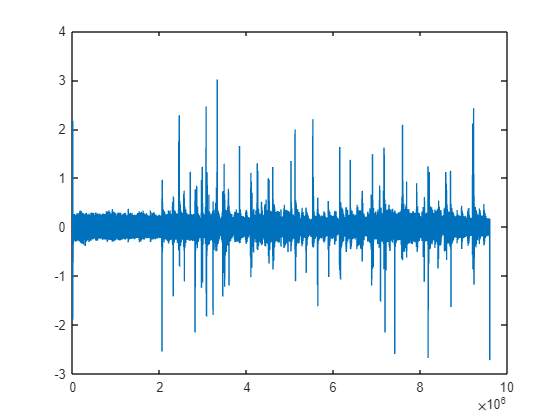

xdld = demod(xdl,Fcd,Fs,"am");
plot(xdld)

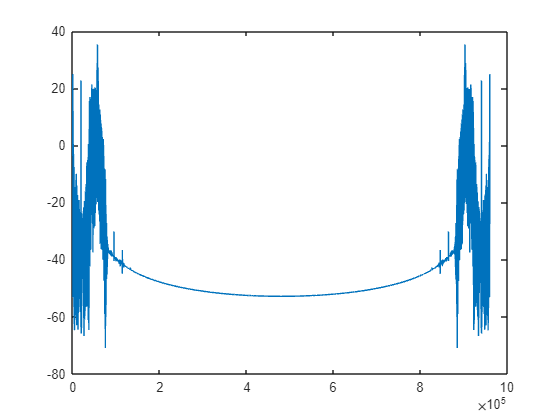

plot(20*log10(abs(fft(xdld, Fs))))

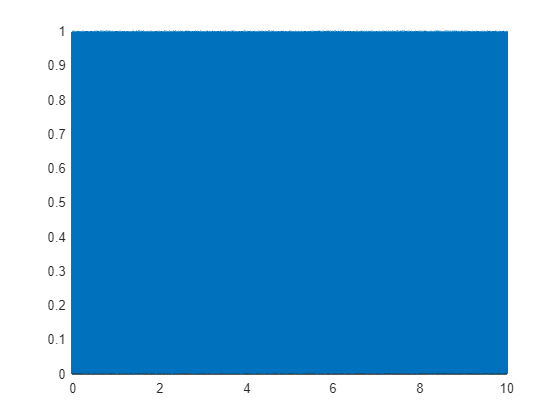

rea = pskdemod(xdl, 2);
bitrate = 1187.5;
plot(t, rea)

nu = nrSymbolDemodulate(xdl', 'pi/2-BPSK')

nu = 1.0e+09 *

    0.0832
   -0.1353
    0.1365
   -0.1452
    0.1552
   -0.1683
    0.1823
   -0.2013
    0.2212
   -0.2447
